assert(isfile("DCS_2D_Disk.mlx"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 35;
disk.n_z = 20;

## Uniform Grid

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)

EM.z = 5.00e-3; % (m)

EM.current = 1; % (A)
EM.Nturns = 60;
EM.current_density = EM.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.angular_frequency = 2*pi*5000; % (rad/s)

#### Model

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildDiskModel(r,z);

calculate geometry took 0.01 seconds


clear r z

Model.conductivity = 3.774e7 * ones(1,Model.num_elms); % (S/m)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 138.85 seconds


#### Solve in frequency domain

Sol = SolveFrequency2D(GoverningEquation, EM);

solve J_Im took 0.00 seconds
solve J_Re took 0.00 seconds


#### Plot result

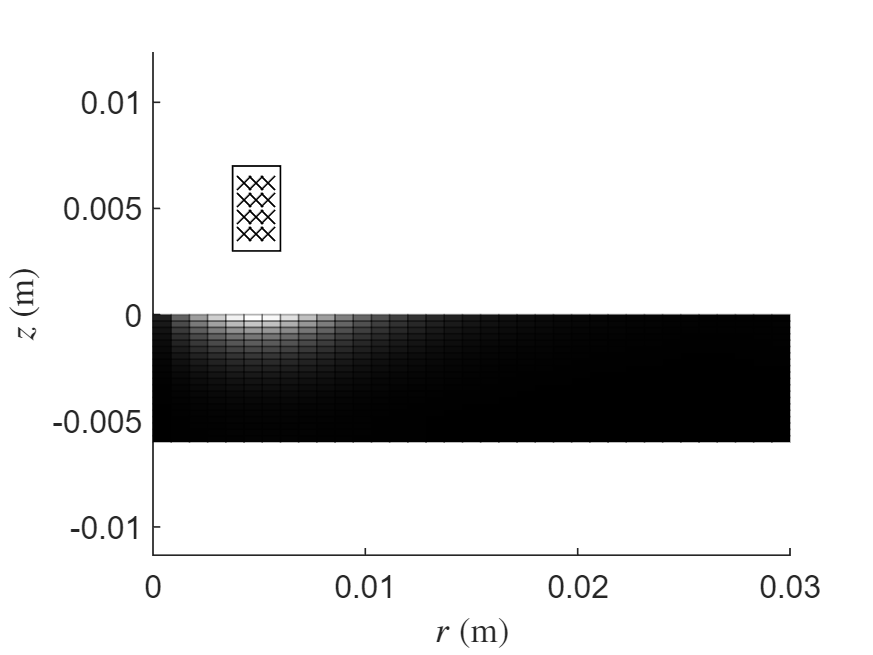

J = hypot(Sol.J_Re, Sol.J_Im);
PlotWorld2D(Model, EM, J);

clear J

## Adaptive Grid

#### Model

J = hypot(Sol.J_Re, Sol.J_Im);
pdf = reshape(J.^-0.5, [disk.n_r, disk.n_z]);
r_cdf = cumsum(pdf(:,end))';  r_cdf = [0 r_cdf] / r_cdf(end);
z_cdf = cumsum(pdf(6,:));     z_cdf = [0 z_cdf] / z_cdf(end);

r = disk.radius * r_cdf;
z = disk.height * z_cdf - disk.height;

Model2 = BuildDiskModel(r,z);

calculate geometry took 0.03 seconds


clear J pdf r_cdf z_cdf r z

#### Plot adaptive grid

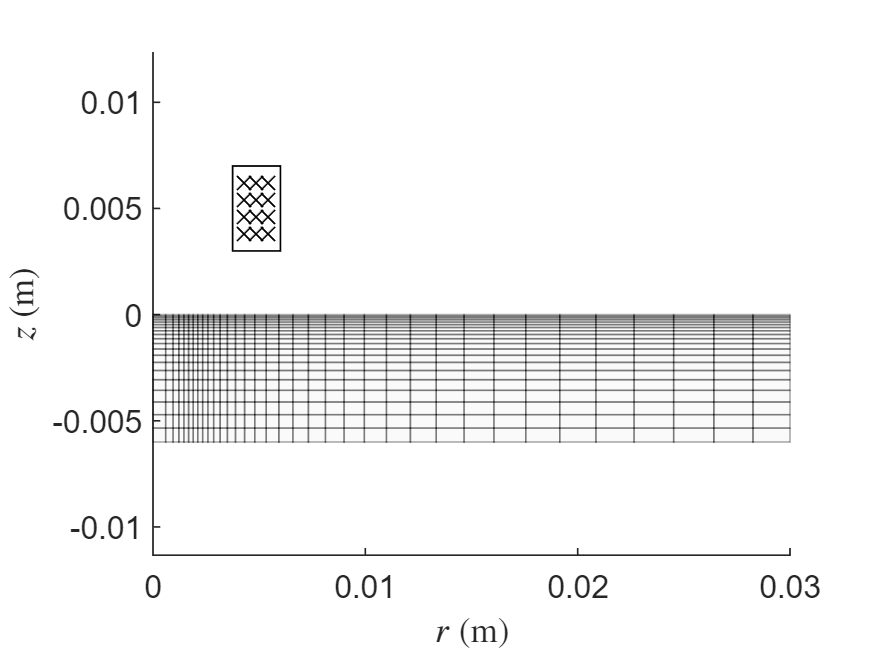

clf;
PlotWorld2D(Model2, EM);

## Compare with FEA

fid = fopen('FEA_data/J.csv');
data = textscan(fid, '%f,%f,%f', 'Delimiter','\n', 'CommentStyle','%');
fclose(fid);
r = reshape(data{1}, 200, []);
z = reshape(data{2}, 200, []);
J = reshape(data{3}, 200, []);
clear ans fid data

#### Plot

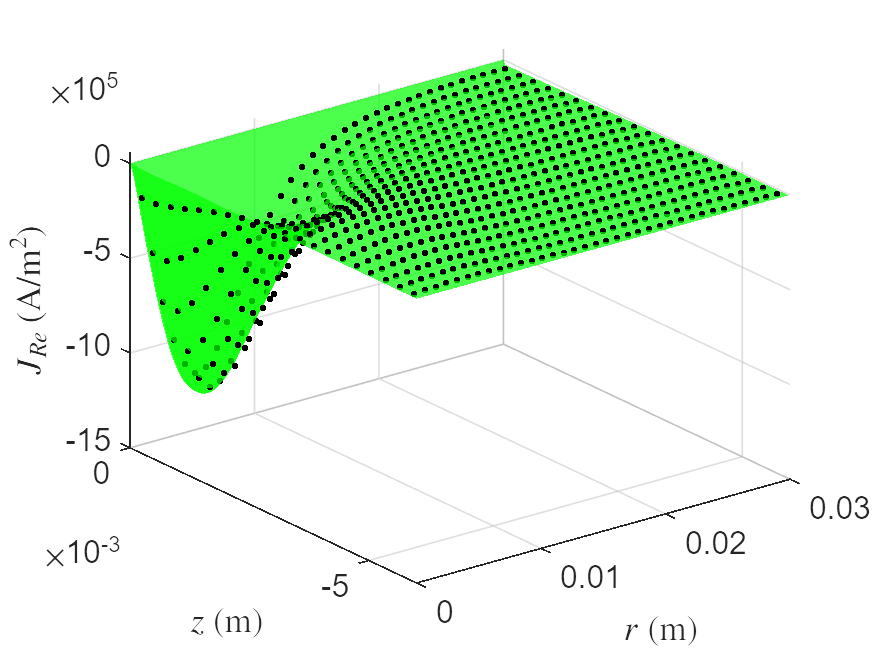

clf
surf(r,z, real(J), 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), Sol.J_Re, 'k.')
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
hold off

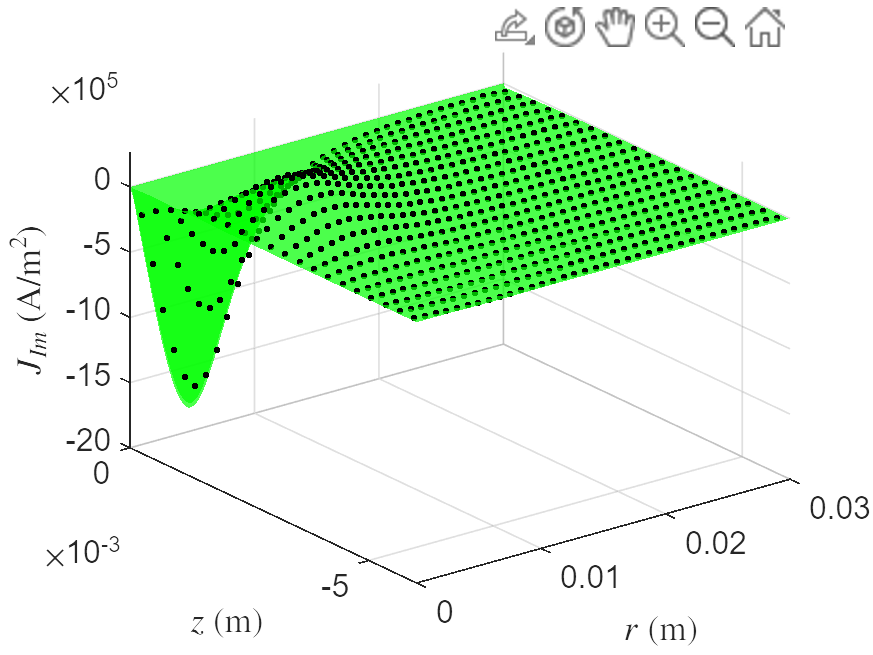


clf 
surf(r,z, imag(J), 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), Sol.J_Im, 'k.')
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
hold off